# Solving an Optimization Problem

Instructions are in the task pane to the left. Complete and submit each task one at a time.

Do not edit. This code replicates what you have done thus far. 

prob = optimproblem("Description","Factory Location");
x = optimvar("x");
y = optimvar("y");
X = [5 40 70];
Y = [20 50 15];
d = sqrt((x-X).^2 + (y-Y).^2);
dTotal = sum(d);
prob.Objective = dTotal;
show(prob)


  OptimizationProblem : Factory Location

	Solve for:
       x, y

	minimize :
       sum(sqrt(((x - extraParams{1}).^2 + (y - extraParams{2}).^2)))

       extraParams





## Task 1

Different types of optimization problems require  different kinds of solvers to be used. In this problem, your objective  function is nonlinear so you need to use a solver that is suitable for  such a function. Fortunately, MATLAB will choose the appropriate solver  for you.

Solvers designed to handle nonlinear objectives require  you to provide an initial guess, which will be used as a starting point  to algorithmically search for the optimal solution. An initial guess  must be provided for each optimization variable in your problem. 

The syntax for providing your initial guess for each variable is:

`initialGuess.varName1` `=` `10`

`initialGuess.varName2` `=` `15`

`initialGuess.varName3` `=` `2`  

Task

Define an initial guess structure named `initialGuess` for your optimization variables `x` and `y`. You may choose any number between 0 and 500 for your initial guesses.

initialGuess.x=40

initialGuess = struct with fields:
    x: 40


initialGuess.y=79

initialGuess = struct with fields:
    x: 40
    y: 79


## Task 2

After defining an initial guess, you can solve the optimization problem using the `solve` function.

`[``sol``,``optval``]` `=` `solve``(``prob``,``x0``)`

 This function takes the optimization problem `prob` and your initial guess `x0` as inputs and returns the solution structure `sol`, which contains the values of the optimization variables that yield the  minimum of the objective function. It also returns the value of the  objective at the solution `optval`.

Task

Use the `solve` function to find the solution to the location problem. Store the outputs in `sol` and `optval`.

[sol, optval]=solve(prob,initialGuess)

Solving problem using fminunc.

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


sol = struct with fields:
    x: 38.9434
    y: 36.2639


optval = 89.0540

## Task 3

In the output pane, notice that MATLAB used the `fminunc` solver to find the solution.

The optimal values of your optimization variables are stored in the solution structure `sol`, and can be accessed using dot notation `sol.varName1`, `sol.varName2`, and so on. 

Task

Extract the optimal values of the x- and y-coordinates from the solution structure `sol`, and store them in variables `xOpt` and `yOpt`, respectively. You may want to leave off the semicolon to display the result. 

xOpt=sol.x

xOpt = 38.9434

yOpt=sol.y

yOpt = 36.2639

This code plots the three stores.

plotStores

## Task 4

The locations of the three stores have been plotted for you using the local function `plotStores`. You can display the optimal location of your factory using the `scatter` function. To plot it in the existing figure, use the `hold` `on` and `hold` `off` commands.

`hold` `on`

`scatter``(``xData``,``yData``)`

`hold` `off`

Task

Plot the optimal x- and y-coordinates of the factory in the current figure.

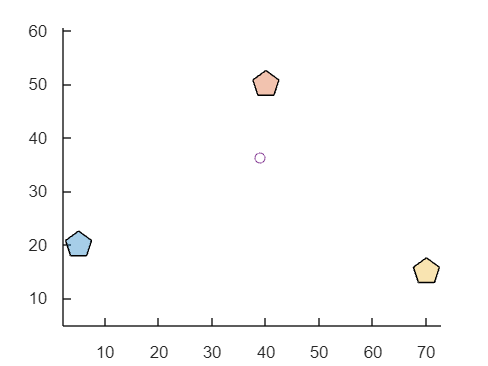

hold on
scatter(xOpt,yOpt)
hold off

## Further Practice

The `evaluate` function can be used to evaluate optimization expressions at a  specified value(s). The following code will evaluate the expression `dTotal` for the total shipping distance at the optimal solution: 

`dTotalEval` `=` `evaluate``(``dTotal``,``sol``)`

 Notice that this gives you the minimum value of the objective function and the same result as `optval`. 

 Alternatively, you could find the optimal distance to each of the stores individually by evaluating `d` at the solution:

`dEval` `=` `evaluate``(``d``,``sol``)`

What do you notice about the sum of `dEval` and `dTotalEval`?

dTotalEval = evaluate(dTotal,sol)

dTotalEval = 89.0540

dEval = evaluate(d,sol)

dEval =    37.6386   13.7767   37.6386


sum(dEval)

ans = 89.0540

Do not edit. This function is used to plot the Supply Center location and Distribution Centers.

function plotStores()
X = [5 40 70];
Y = [20 50 15];
pgon1 = nsidedpoly(5,"Center",[X(1) Y(1)],"sidelength",3);
pgon2 = nsidedpoly(5,"Center",[X(2) Y(2)],"sidelength",3);
pgon3 = nsidedpoly(5,"Center",[X(3) Y(3)],"sidelength",3);
plot([pgon1 pgon2 pgon3])
axis equal
end